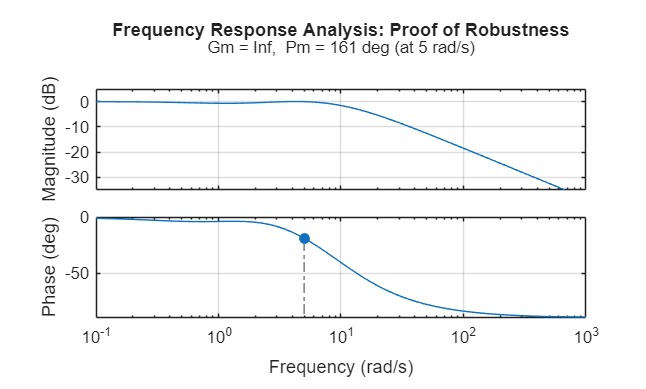

% Closed-loop system with your current parameters
s = tf('s');
G = 1/(s^2 + 2*s + 5);
C = 40 + 25/s + 12*s;
T = feedback(C*G, 1);

% Frequency Response for the Pitch
figure;
margin(T); % Generates the Bode plot with stability margins
grid on;
title('Frequency Response Analysis: Proof of Robustness');